## Drone Classification Toolbox

This document is for the MathWorks drone classification project. The package dsecribed in this document implemented

- **"binary"**: the `drone` and `non-drone` binary classification

- "**drone-classification**": the 5 different type of drones classification

- "**four-class**": `drone`, `bird`, `cluster`, and `noise`

The package provide the following neural networks:

- resnet18

- resnet50

- efficientnet_v2_s

- efficientnet_v2_m

- resnext50_32x4d

- alexnet

## import package

import classification.*

## read an image

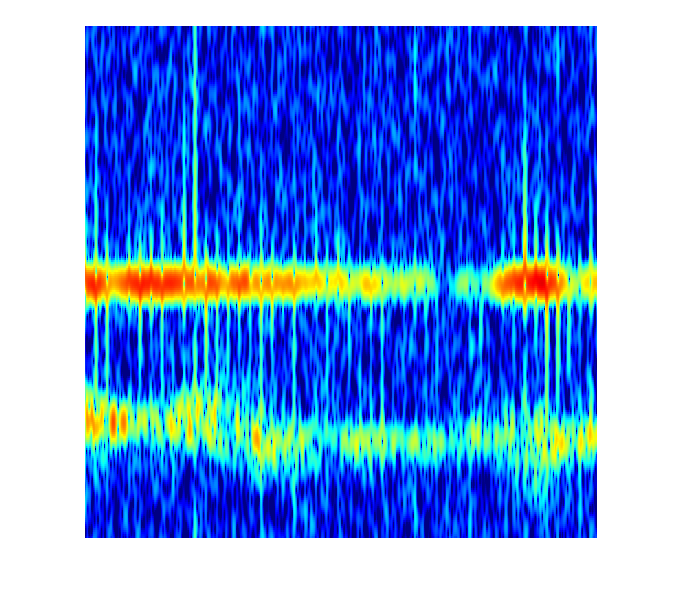

img_path = './data/94GHz/non-drone/interval_0.25_wd_256/2024-02-06_11-22-25/0.png';
img = imread(img_path);
imshow(img);

## create an object of our model

net = classification.ClassificationNet('alexnet','binary');

## use the network to predict

pred = net.predict_label(img);
disp(pred);

non-drone
